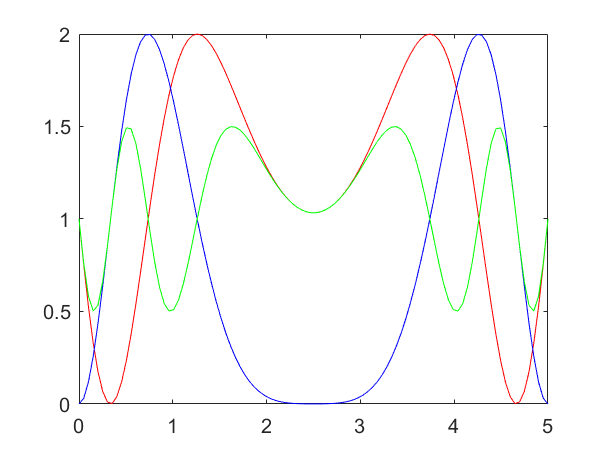

% Question (a)
x=linspace(0,5,100);
y1=1-sin(x.*(5-x));
y2=1-cos(x.*(5-x));
y3=1-sin(x.*(5-x)).*cos(x.*(5-x));
plot(x,y1,'r',x,y2,'b',x,y3,'-g')

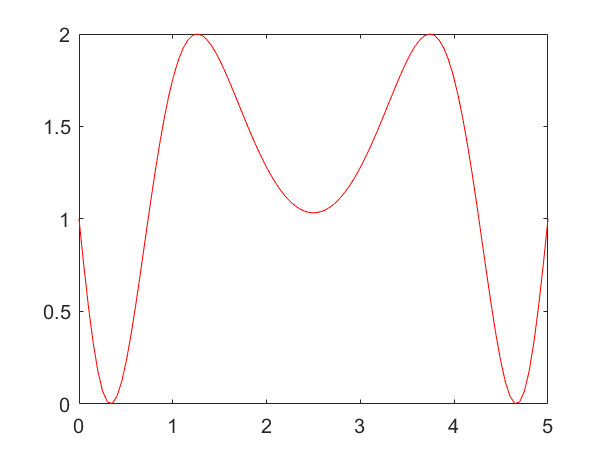

% Question (b)
figure(1)
plot(x,y1,'r');

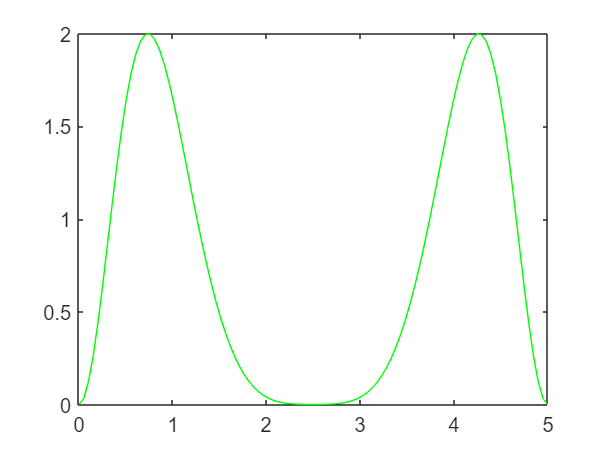

figure(2)
plot(x,y2,'g');

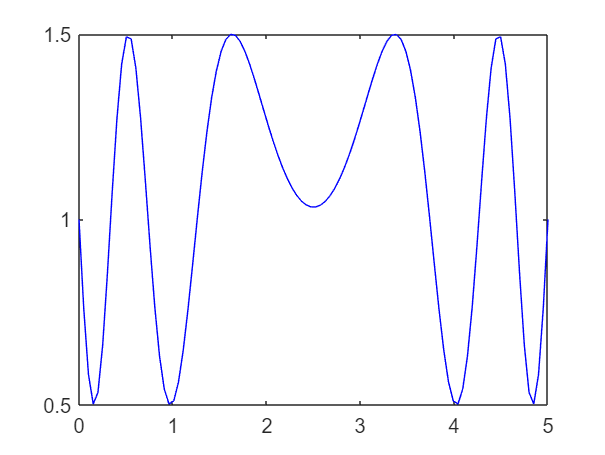

figure(3)
plot(x,y3,'b');

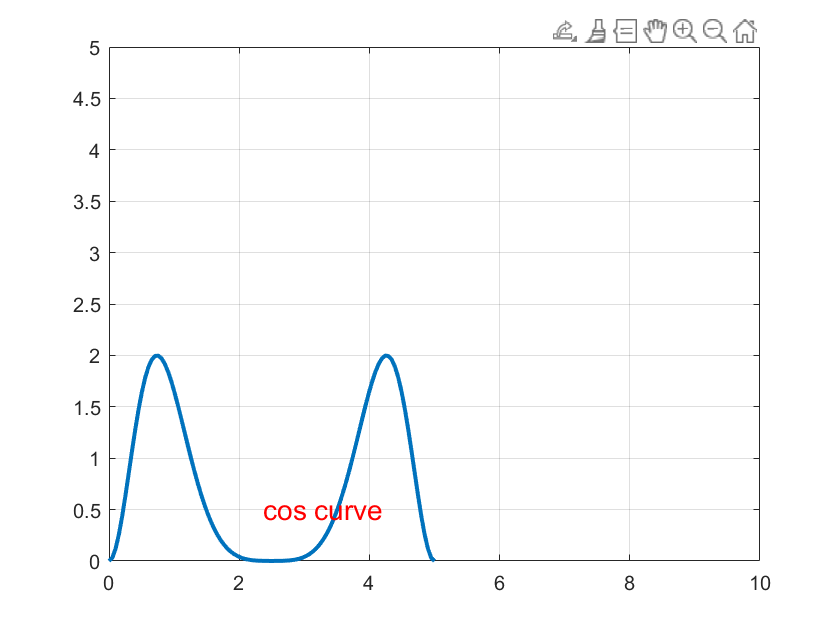

% % Question (c)
% x=linspace(0,5,100);
% y1=1-sin(x.*(5-x));
% plot(x,y1,'r');
% xlabel('\bf x axis');ylabel('\fontsize{18}y axis');
% title('Sine plot');
% xticks([0 .5 1 2 3 4 5]);
% xticklabels({0,1/2,1,2,3,4,5});
% legend('1-sin(x(5-x))','-cos(x(5-x))','1-sin(x(5-x))cos(x(5-x))','location','best');
% Question (d)
plot(x,y2,'linewidth',2); grid on; 
gtext('cos curve','color','red','Fontsize',14);
axis([0,10,0,5]);

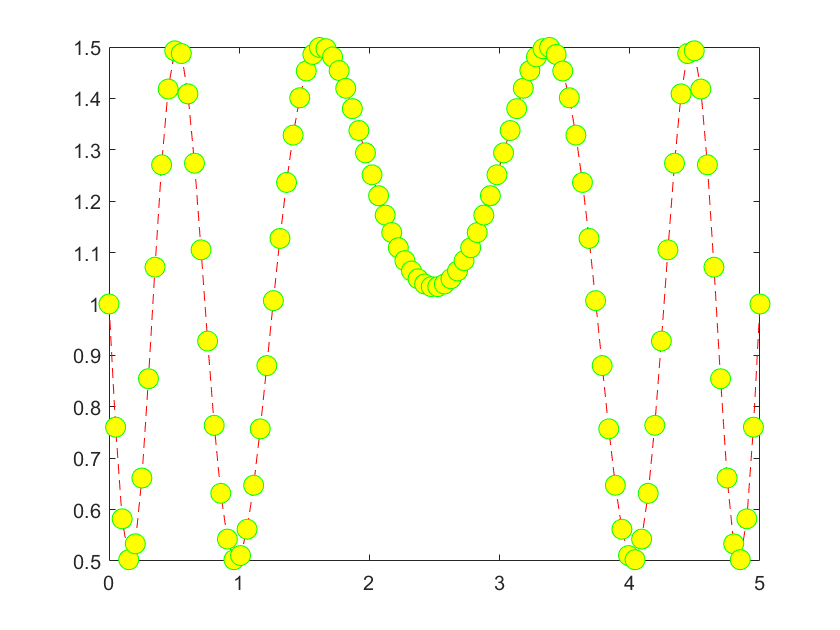

% Question (e)
plot(x,y3,'--redo','markersize',10,'MarkerEdgeColor','green','MarkerFaceColor','yellow');

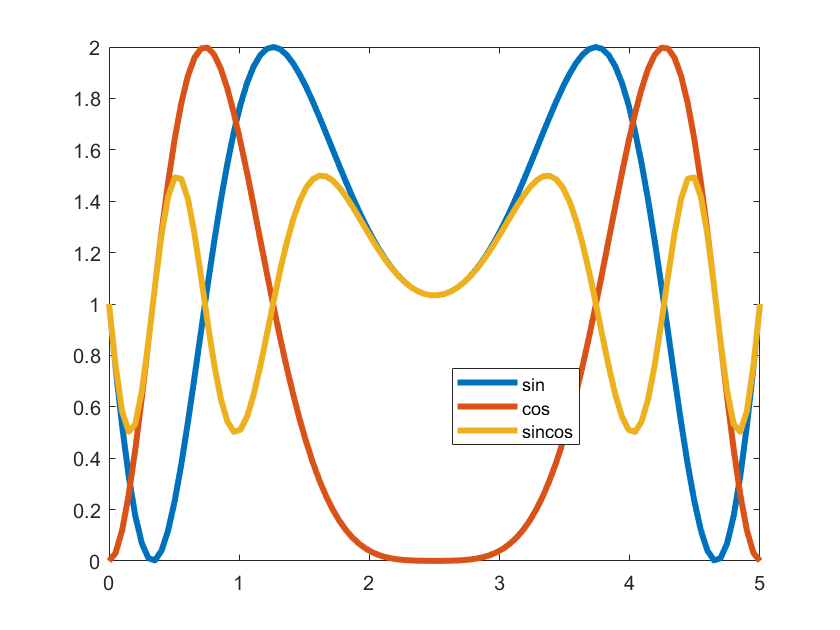

% Question (f)
plot(x,y1,x,y2,x,y3,'linewidth',3);
legend('sin','cos','sincos','location','best');

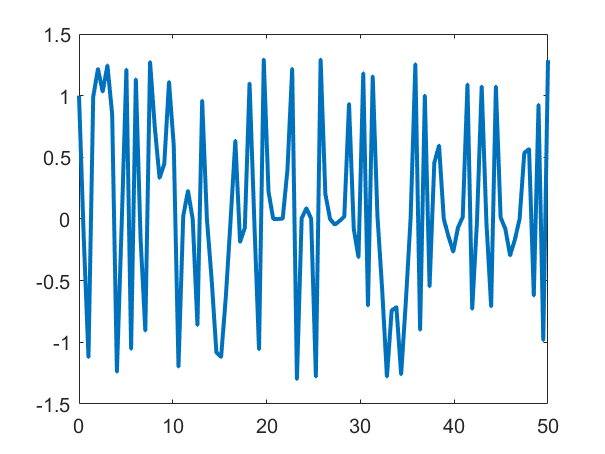

% Question (g)
f=@(x) (1-sin(x.*(5-x))).*cos(x.*(5-x));
x=linspace(0,50,100);
plot(x,f(x),'linewidth',2);
print(gcf,'-dpng','-r300','Plot.Exmp.png')

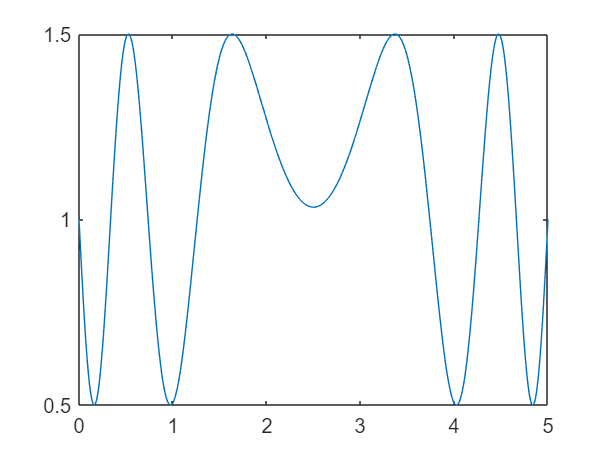

% Question (h)
fplot('1-sin(x*(5-x))*cos(x*(5-x));',[0,5]);

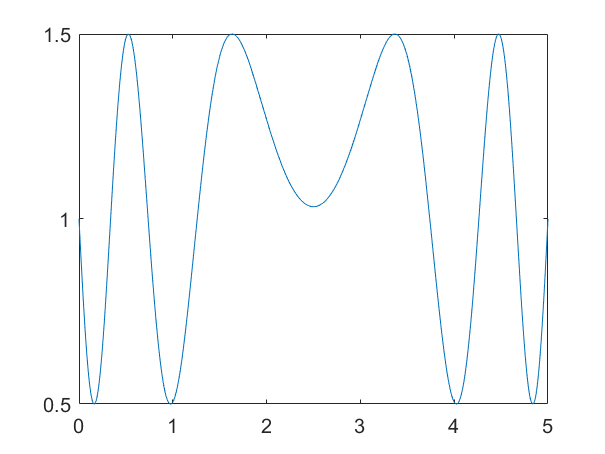

% Question (h)
f=@(x) (1-sin(x.*(5-x)).*cos(x.*(5-x)));
fplot(f,[0,5]);

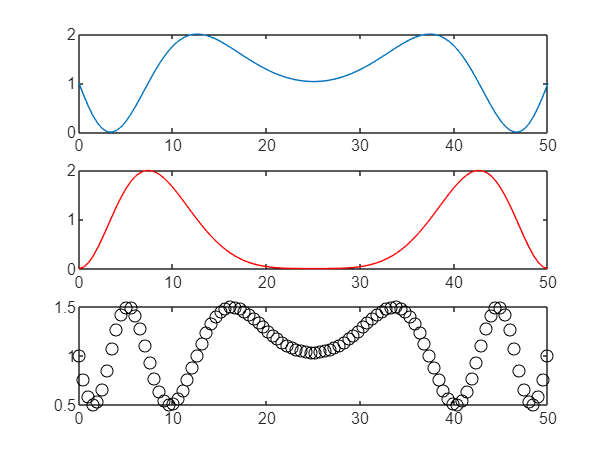

% Question (i)
subplot(3,1,1);plot(x,y1);
subplot(3,1,2);plot(x,y2,'r');
subplot(3,1,3);plot(x,y3,'ok');